# Part 0: 導入

電力系統がどのような設備で、なぜ需要と供給を常に一致させなければならないのか、そしてどの解析がどの問いに答えるのかを、GUILDA で計算しながら確かめます。系統モデルの読み込み、潮流計算、事故の時間シミュレーションを一通り実行し、最後に慣性が小さくなると周波数の動きがどう変わるかを計算で比べます。

**この Part で分かること**

- 電力系統の 4 つの段階（発電・送電・配電・需要）と、高い電圧で送る理由

- 需要と供給を常に一致させる理由と、周波数・電圧が表すもの（発電機ごとの動揺方程式と系統周波数）

- 電力系統の現象の時間スケールと、解析ごとに注目する範囲

- 潮流計算と時間シミュレーションが、それぞれ何を求める計算か

- 慣性が小さくなると、発電機が脱落したときの周波数の低下がどう変わるか

知識ページ: [Part 0: 導入](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part0-introduction.html","-browser"))（クリックするとブラウザで開きます）。知識ページの図は、このライブスクリプトを実行すると描けます。

**注意**: 実行する前に、GUILDA のフォルダで `GUILDA` を実行してパスを通しておきます。上のリンクも、このパスから知識ページの場所を求めて開きます。全体の実行には 1〜2 分かかります。

## 0. 図の色

この Part の図は、知識ページと同じ配色で描きます。色を RGB（0〜1）で決めておきます。

sct_color.rr_brand = [0, 89, 167] / 255;    % 青: 主役の量
sct_color.rr_c2    = [46, 107, 63] / 255;   % 緑: 時間応答・動的な現象
sct_color.rr_c3    = [154, 91, 0] / 255;    % 橙: 比べる相手・静的な解析
sct_color.rr_c4    = [122, 62, 143] / 255;  % 紫: 制御
sct_color.rr_tint  = [238, 243, 248] / 255; % 淡い青: 範囲の帯

## 1. 発電所から需要家まで

電力系統は、電気をつくって需要家に届けるための設備全体です。発電所で電気をつくる**発電**、高い電圧で遠くまで運ぶ**送電**、町の中で低い電圧にして配る**配電**、そして電気を使う家庭・事務所・工場などの**需要**の 4 つの段階からなります。送電網は一本の鎖ではなく、多くの発電所と変電所が網の目のようにつながっています。解析では、この網の目を**母線**（接続点）と、それらを結ぶ**ブランチ**（送電線や変圧器）で表し、発電機や負荷を母線につなぎます。

同梱の IEEE 68 母線系統（ニューイングランドとニューヨークの系統を模した 16 機の系統）を読み込み、母線とブランチの数を数えます。関数 `network.IEEE68bus` は、部品がすべてつながり、運転状態（平衡点）まで求めた系統モデルを返します。

net = network.IEEE68bus(LocalController=true);
tab_element = net.get_element_table(Kind=["bus", "branch", "component"]);
groupcounts(tab_element, "Kind")

ans = 3×3 table
       Kind        GroupCount    Percent
    ___________    __________    _______

    "branch"           83        41.089 
    "bus"              68        33.663 
    "component"        51        25.248 


`get_element_table` は、系統の部品を 1 行に 1 つずつ並べた表を返します。種類（`Kind`）ごとに数えると、68 個の母線と、それを結ぶ 83 本のブランチからなる網の目に、発電機と負荷（`component`）がつながっていることが分かります。つながり方を系統図で見ます。

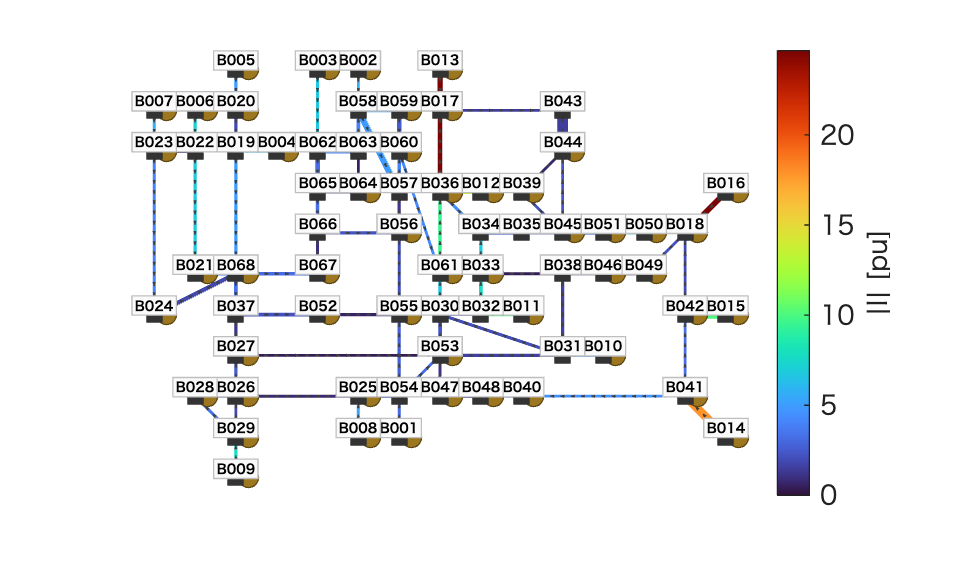

G = net.plot_diagram();

発電機（タグ `SG`）と負荷（タグ `LRX`）が母線につながり、母線どうしがブランチで結ばれています。ブランチの色は流れる電流の大きさを、太さはブランチのアドミタンスの大きさ（つながりの強さ）を表します。どの母線にも 2 本以上のブランチがつながる部分が多く、1 本の送電線が使えなくなっても別の経路で電力が流れることが分かります。

**注意**: 図は拡大でき、要素にカーソルを合わせるとその値が表示されます。色で表す量はメソッド `plot_diagram` の名前と値の引数 `ColorMode` で変えられます（既定値 `"I"`）。系統モデルの作り方は Part 1 で扱います。

### 高い電圧で送る理由

三相の送電線で有効電力 $P$ を線間電圧 $V$、力率 $\cos\varphi$ で送ると、電線を流れる電流は $I = P / (\sqrt{3}\,V\cos\varphi)$ です。1 相あたりの抵抗を $R$ とすると、3 相の電線で熱になって失われる電力（損失）は次のとおりです。


$$P_\mathrm{loss} = 3RI^2 = \frac{R\,P^2}{V^2\cos^2\varphi}$$


同じ電力を送るなら、損失は電圧の 2 乗に反比例します。1000 MW を、1 相あたり 10 Ω の送電線で力率 1 として送るときの損失を、電圧ごとに計算します。

r_P = 1000e6;                        % [W] 送る電力
r_R = 10;                            % [Ω] 1 相あたりの抵抗
rv_V = [154; 275; 500] * 1e3;        % [V] 線間電圧
rv_loss = r_R * r_P^2 ./ rv_V.^2;    % [W] 損失（力率 1）
rm_loss = [rv_V / 1e3, rv_loss / 1e6, 100 * rv_loss / r_P]   % 列: V (kV)、損失 (MW)、損失 (%)

rm_loss =   154.0000  421.6563   42.1656
  275.0000  132.2314   13.2231
  500.0000   40.0000    4.0000


154 kV では送る電力の 4 割を超える損失が、500 kV では 4 % に収まります。そのため、発電機の後で変電所の変圧器が電圧を上げて遠くまで送り、需要家に近づくにつれて段階的に下げていきます。

## 2. 需要と供給を常に一致させる

送電網そのものは、電気エネルギーをほとんど蓄えられません。そのため、発電機がつくる電力は、需要家が使う電力と損失の合計に、いつの瞬間も等しくなければなりません。これを**同時同量**といいます。

需給のずれを最初の数秒間まかなうのは、同期発電機の回転子と、それにつながるタービンに蓄えられた運動エネルギーです。需要が供給より多いと、その差がこの運動エネルギーから取り出されて回転子が減速し、周波数が下がります。供給が需要より多いと回転子が加速し、周波数が上がります。

電力系統には多くの同期発電機があり、それぞれが自分の回転子を持っています。発電機 $i$（$i = 1, \dots, m$）の回転子の動きは、その発電機の動揺方程式で表されます。


$$M_i\,\frac{\mathrm{d}\omega_i}{\mathrm{d}t} = P_{\mathrm{m},i} - P_{\mathrm{e},i} - D_i\,\omega_i$$


$\omega_i$ は定格の速さからのずれ（pu）で、回転子は定格の速さの $1 + \omega_i$ 倍で回っています。$M_i$（s）は慣性定数、$D_i$（pu）は制動の大きさ、$P_{\mathrm{m},i}$ は機械入力です。GUILDA の発電機も、この $\omega_i$ を状態に持ち、慣性を $M_i$ で表します。電気出力 $P_{\mathrm{e},i}$ は、発電機 $i$ が送電網に送り出す電力です。これは送電網の方程式から決まり、すべての発電機の回転子の角度と内部電圧、そして負荷によって変わります。発電機どうしは、このように送電網を通して結び付いています。1 台の発電機の式だけを取り出して解くことはできません。

母線もそれぞれ自分の周波数を持ちます。母線の周波数は、その母線の電圧の位相角が変わる速さで決まります。外乱の後に発電機が揺れている間は、母線の周波数は母線ごとに異なり、発電機の速さとも一致しません。系統が安定であれば揺れは収まり、すべての発電機が同じ速さで回る同期した状態になります。このときは、どの母線で測っても周波数は同じ値になります。この共通の値が系統周波数です。

同期した定常状態では、どの発電機でも $\mathrm{d}\omega_i/\mathrm{d}t = 0$ で、速さのずれは共通の値 $\omega_\mathrm{s}$ になります。$m$ 本の動揺方程式を足し合わせると、次の式が得られます。


$$\omega_\mathrm{s} = \frac{\sum_i P_{\mathrm{m},i} - \sum_i P_{\mathrm{e},i}}{\sum_i D_i}$$


電気出力の和は、負荷が消費する電力と損失の和です。機械入力を変えない（ガバナと AGC がない）とき、機械入力の和がこれより小さければ $\omega_\mathrm{s} < 0$ となり、系統は定格より低い周波数で同期します。周波数がひとりでに定格値 $f_0$ に戻ることはありません。ガバナはずれを小さくしますが、一部は残ります。AGC は周波数が $f_0$ に戻るまで機械入力を変えます（5 節と Part 8）。

動揺方程式の和は、慣性で重み付けした速さの平均、つまり慣性中心（COI）の速さ $\omega_\mathrm{COI} = \sum_i M_i\omega_i / M_\mathrm{T}$ を使っても書けます。$M_\mathrm{T} = \sum_i M_i$ は慣性の合計です。


$$M_\mathrm{T}\,\frac{\mathrm{d}\omega_\mathrm{COI}}{\mathrm{d}t} = \sum_i P_{\mathrm{m},i} - \sum_i P_{\mathrm{e},i} - \sum_i D_i\,\omega_i$$


この式は動揺方程式から正確に導けますが、系統全体のモデルではありません。$m$ 台の発電機に対して式は 1 本だけで、電気出力の和はすべての角度と電圧に依存します。個々の発電機の揺れや、母線ごとの周波数の違いは、この式からは分かりません。この式から分かるのは、慣性の合計の効果です。需給のずれが急に生じると、慣性中心の周波数は、そのずれを $M_\mathrm{T}$ で割った傾きで変わり始めます。たとえば需要が急に $\Delta P$ 増え、それを発電機がすぐに受け持つとき（損失のない送電網と定電力負荷ではちょうどそうなります）、傾きは $-\Delta P / M_\mathrm{T}$ です。慣性の合計 $M_\mathrm{T}$ が大きいほど、最初の変化はゆっくりになります。5 節で、この傾きを時間シミュレーションの結果と比べます。

同期した系統の周波数と違い、電圧の大きさは母線ごとに異なる値になり、主に無効電力のつり合いで決まります。周波数も電圧も、機器が定格の値で動くように作られているため、決められた範囲に保つ必要があります。

## 3. 系統で起きる現象と時間スケール

電力系統では多くの現象が同時に起きていますが、その時間の長さは大きく異なります。一つの解析ですべてを扱うことはできないため、解析ごとに注目する範囲を決め、それより速い現象や遅い現象は簡単化して扱います。現象ごとのおおよその時間の範囲を、対数目盛りの横軸に並べます。

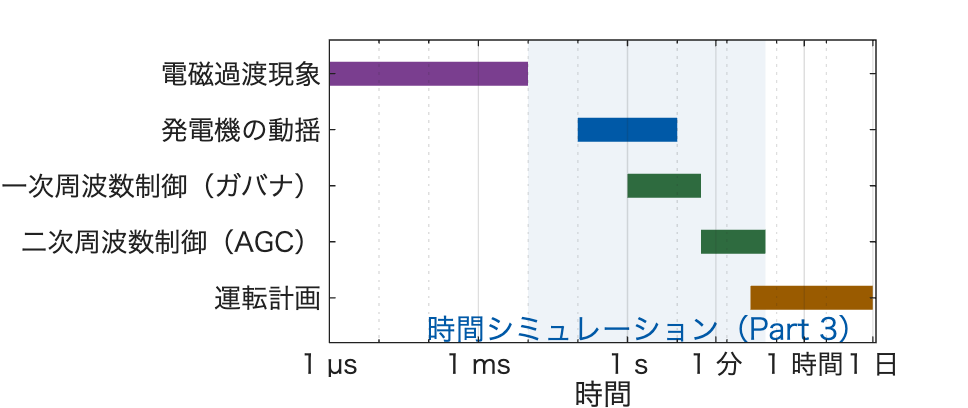

rm_range = [1e-6, 1e-2; 0.1, 10; 1, 30; 30, 600; 300, 86400];   % [s] 各現象のおおよその範囲（上から）
rr_sim = [1e-2, 600];                                             % [s] 時間シミュレーションで主に扱う範囲
sr_name = ["電磁過渡現象", "発電機の動揺", "一次周波数制御（ガバナ）", "二次周波数制御（AGC）", "運転計画"];
n_bar = size(rm_range, 1);

figure(Position=[100, 100, 900, 380]);
ax = axes(XScale="log", XLim=[1e-6, 1e5], YLim=[0.4, n_bar + 0.8], YDir="reverse", ...
    YTick=1:n_bar, YTickLabel=sr_name, XTick=[1e-6, 1e-3, 1, 60, 3600, 86400], ...
    XTickLabel=["1 µs", "1 ms", "1 s", "1 分", "1 時間", "1 日"], XGrid="on", Box="on");
hold(ax, "on");
patch(ax, rr_sim([1, 2, 2, 1]), [0.4, 0.4, n_bar + 0.8, n_bar + 0.8], sct_color.rr_tint, EdgeColor="none");
text(ax, sqrt(prod(rr_sim)), n_bar + 0.55, "時間シミュレーション（Part 3）", ...
    HorizontalAlignment="center", Color=sct_color.rr_brand);
rm_barColor = [sct_color.rr_c4; sct_color.rr_brand; sct_color.rr_c2; sct_color.rr_c2; sct_color.rr_c3];
for i_bar = 1:n_bar
    plot(ax, rm_range(i_bar, :), [i_bar, i_bar], Color=rm_barColor(i_bar, :), LineWidth=9);
end
ax.Layer = "top";
xlabel(ax, "時間");

色の付いた帯が、時間シミュレーションで主に扱う範囲です。範囲は重なり合い、系統によっても変わります。

- **電磁過渡現象**（マイクロ秒〜ミリ秒）: 雷や遮断器の開閉で生じるサージが送電線を伝わります。絶縁の設計で重要になります。

- **発電機の動揺**（0.1〜10 秒）: 事故の後、発電機の回転子どうしが揺れ合います。元の歩調に戻れるかどうかが安定度の問題です（Part 3 と Part 5）。

- **周波数制御**（数秒〜数分）: ガバナが数秒のうちに発電機の出力を変えて周波数の変化を止め、自動発電制御（AGC）が数十秒から数分かけて周波数を元に戻します（Part 8）。

- **運転計画**（数分〜1 日）: どの発電機をどれだけ動かすかを、費用を抑え、設備の限界を守るように計画します（Part 6）。

GUILDA の時間シミュレーションは、電圧や電流を交流の振幅と位相（フェーザ）で表します。交流の 1 周期（60 Hz なら約 17 ms）より速い変化は追わないので、電磁過渡現象は扱わず、発電機の動揺とそれに続く制御の動きを調べます。潮流計算、最適潮流計算、連続潮流計算には時間の軸がなく、ある瞬間の運転状態を求めます。

## 4. 解析の種類：潮流計算と時間シミュレーション

どの解析も系統のモデル（Part 1）から始まり、次に潮流計算（Part 2）で定常的な運転状態を求めます。これがほかの解析の出発点です。その先には、ある瞬間の状態のまま費用や限界を調べる解析（最適潮流計算 Part 6、連続潮流計算 Part 7）と、時間とともに変わる揺れを追う解析（時間シミュレーション Part 3、近似線形化 Part 5）があります。ここでは、出発点の潮流計算と、揺れを追う時間シミュレーションを実行して、2 つの違いを見ます。

### 4.1 潮流計算：ある瞬間の運転状態

潮流計算は、発電と負荷を決めたときの各母線の電圧と各送電線の電力を求めます。時間を含まない連立方程式（電力方程式）を解く計算で、答えは 1 組の数値です。

resPF = net.calculate_powerflow();
resPF.disp_summary()

Power flow of PowerNetwork (Solver newton): converged, flag 1
- Calculation: 0 iterations, largest residual 6.48e-11 pu, elapsed 0.0325 s
- Message: ✔ The Newton-Raphson iteration has converged within the tolerance limit (0 iterations).
- Network: 68 buses (slack 1, PV 15, PQ 52), 83 branches
- Generation: P = 177.8753 pu, Q = 24.9600 pu
- Load: P = 176.2070 pu, Q = 19.7176 pu
- Losses: P = 1.6683 pu, Q = 5.2424 pu
- |V|: max 1.0634 pu at B051, min 0.8367 pu at B064
- Violated operating limits: 0


表示の 1 行目で計算が収束したことが分かります。表示した値は `get_summary` で構造体として受け取れます。発電の合計と負荷の合計の差が、送電の損失です。母線ごとの電圧の大きさを棒グラフで見ます。

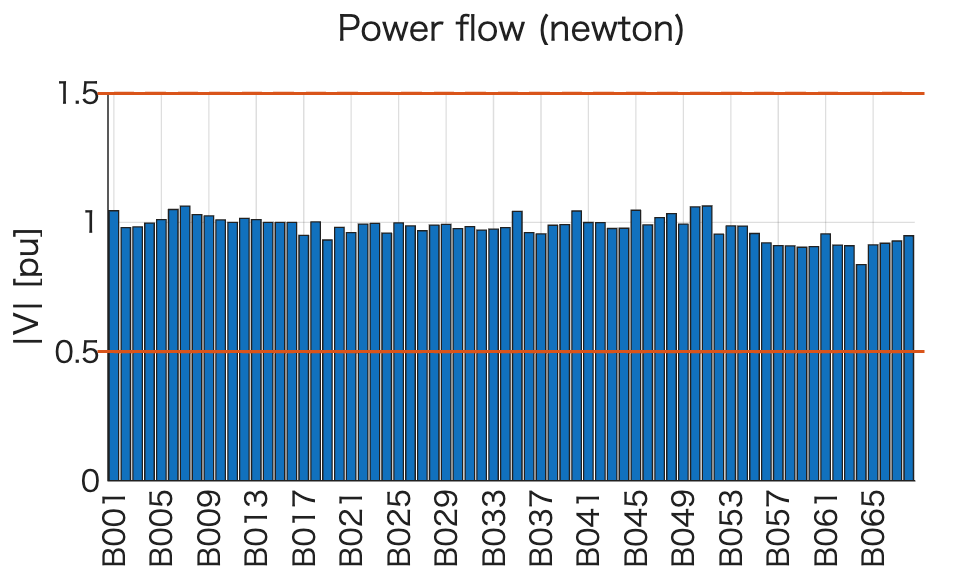

resPF.plot_voltage(Quantity="magnitude");

sct_PF = resPF.get_summary();
[sct_PF.r_Vmin, sct_PF.r_Vmax]   % [pu] 最も低い電圧と最も高い電圧

ans =     0.8367    1.0634


[sct_PF.s_VminBus, sct_PF.s_VmaxBus]

ans = 1×2 の string 配列
    "B064"    "B051"


n_out = sum(resPF.tab_bus.V < 0.95 | resPF.tab_bus.V > 1.05)   % 0.95〜1.05 pu の外にある母線の数

n_out = 18

68 母線のうち 50 母線の電圧は 1 pu の ±5 % 以内にありますが、残りの 18 母線はその外にあり、最も低い B064 は 0.84 pu、最も高い B051 は 1.06 pu です。同梱のデータのままの運転状態でも、電圧には母線ごとにこれだけの幅があります。周波数と違い、電圧は母線ごとに異なる値になることが分かります。潮流計算の考え方と結果の読み方は Part 2 で扱います。

### 4.2 時間シミュレーション：事故の後の揺れ

時間シミュレーションは、潮流計算で求めた運転状態（平衡点）を出発点にして、外乱の後の発電機の動きを、時間について微分方程式を解いて求めます。答えは時間の関数です。ここでは、母線 `B040` で 1.00 秒から 1.07 秒まで地絡が起き、その後に取り除かれる事故を 10 秒間計算します。まずシナリオ（何が、いつ起きるか）を作り、それを計算します。

sc = net.add_scenario("fault", Time=[0, 10]);
sc.add_fault("B040", [1.00, 1.07]);
resODE = net.simulate("fault");

各発電機の回転速度のずれ $\omega$（pu）を時間に対して描きます。

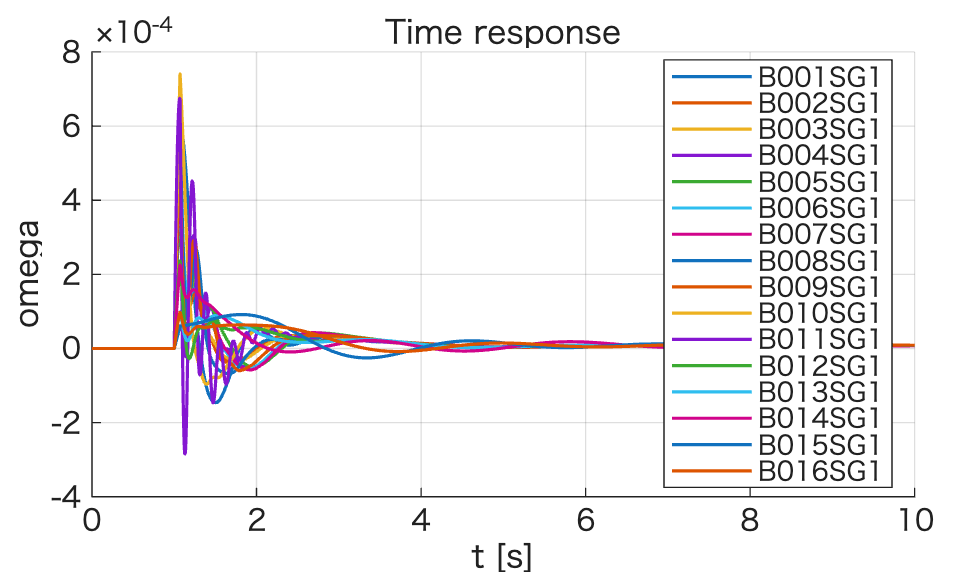

resODE.plot_trajectory(Quantity="omega");

事故の間は母線の電圧が下がって発電機が電力を送り出せなくなり、タービンからの機械入力が電気出力を上回るので、回転子が加速します（2 節の動揺方程式によります。動揺方程式は Part 1 と Part 3 で扱います）。速さのずれは最大でも $10^{-3}$ pu（60 Hz で 0.06 Hz）より小さい値です。事故を取り除いた後は、発電機どうしが 1 秒ほどの周期で揺れ合いながら、数秒で収まっていきます。事故点の母線と、その近くの母線の電圧の大きさも描きます。

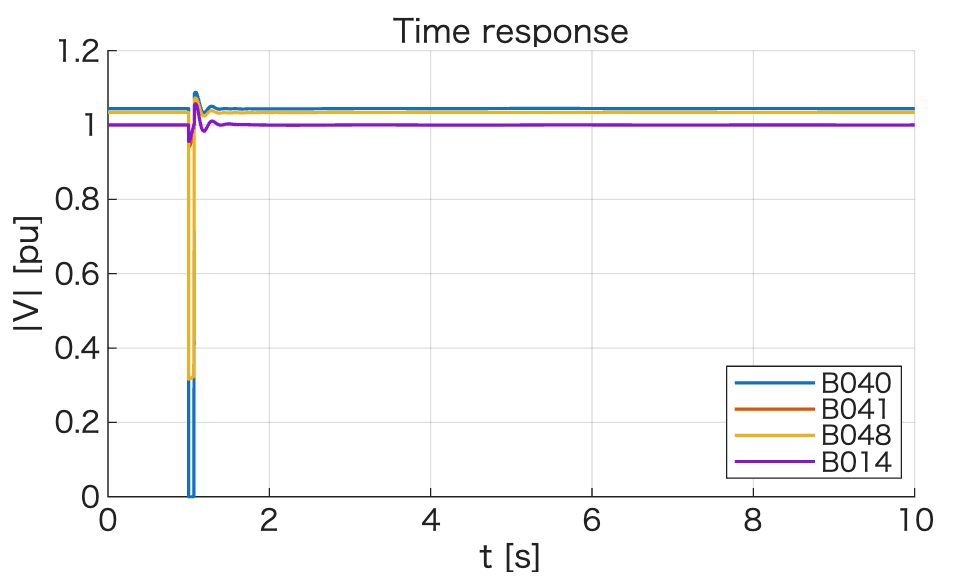

resODE.plot_trajectory(Quantity="Vabs", Bus=["B040", "B041", "B048", "B014"]);

事故の間（1.00〜1.07 秒）は事故点の電圧が 0 になり、近くの母線の電圧も大きく下がります。事故を取り除くと、少し揺れた後に元の値の近くに戻ります。最後に、発電機が同期を保てたかどうかを回転子の角度から判定します。

resODE.judge_out_of_step()

ans = フィールドをもつ struct:
      Verdict: "stable"
         Time: NaN
        Units: [0×1 string]
     MaxAngle: 33.9931
    Reference: "B016SG1"
    Threshold: 360


`Verdict` が `"stable"` なら、どの発電機も脱調せずに揺れが収まったことを表します。事故の時間を長くすると、加速した回転子が戻れなくなり、脱調することがあります（Part 3 で扱います）。

**注意**: シナリオの書き方と、メソッド `simulate` の名前と値の引数は Part 3 で扱います。計算中は、進み具合を示す図が表示されます。

## 5. 再生可能エネルギーが増えると何が変わるか

太陽光発電や多くの風力発電は、系統と同じ速さで回る大きな回転子ではなく、インバータ（パワーエレクトロニクスの変換器）を通して系統につながります。これらが従来の発電所に置き換わると、慣性の合計 $M_\mathrm{T}$ が小さくなります。2 節の慣性中心の式によれば、同じ需給のずれでも、外乱の直後の周波数はより速く変わるはずです。これを時間シミュレーションで確かめます。

同梱の IEEE 9 母線系統（60 Hz、発電機 3 台）の各発電機にガバナ `gov-LPT1` を、系統全体に AGC `agc-PI` を付けます。$t = 1$ 秒で母線 2 の発電機の機械入力を 0.1 pu 減らし（出力の一部が失われた場合に相当）、60 秒間計算します。発電機の慣性 $M$ が同梱のままの場合と、すべての発電機の $M$ を 3 分の 1 にした場合（回転機の一部がインバータの電源に置き換わった場合に相当）を比べます。

r_tend = 60;            % [s] 計算する時間
r_dP = -0.1;            % [pu] 機械入力の変化
rr_scale = [1, 1/3];    % 慣性 M にかける倍率
sr_gen = ["B001SG1", "B002SG1", "B003SG1"];

rc_res = cell(1, 2);
rv_sumM = zeros(1, 2);  % [s] 慣性 M の合計
for i_case = 1:2
    net9 = network.IEEE9bus(LocalController=true);
    tab_dyn = net9.get_parameter("dynamics", Key="gen-1axis");   % 3 台の発電機の M、D など
    tab_dyn.M = tab_dyn.M * rr_scale(i_case);
    net9.set_parameter("dynamics", tab_dyn(:, "M"));
    rv_sumM(i_case) = sum(tab_dyn.M);
    for s_gen = sr_gen
        gen = net9.get_element(s_gen);
        % ガバナの定格出力は、潮流計算の出力を負荷率 0.8 で割ったものにする
        gen.add_local_controller("gov-LPT1", parameter=struct(Prate=gen.rv_Uequilibrium(1) / 0.8));
    end
    net9.add_global_controller("agc-PI", sr_gen, parameter=struct(kP=0, kI=2));
    net9.initialize();
    sc9 = net9.add_scenario("loss", Time=[0, r_tend]);
    sc9.add_input("B002SG1", "Pmech", r_dP, [1, r_tend]);
    rc_res{i_case} = net9.simulate("loss", Progress="none");
end

INFO: The global controller 'PowerNetworkAGC1' is connected: Pmech_B001SG1_PowerNetworkAGC1 -> Pmech_B001SG1; Pmech_B002SG1_PowerNetworkAGC1 -> Pmech_B002SG1; Pmech_B003SG1_PowerNetworkAGC1 -> Pmech_B003SG1.
INFO: The global controller 'PowerNetworkAGC1' is connected: Pmech_B001SG1_PowerNetworkAGC1 -> Pmech_B001SG1; Pmech_B002SG1_PowerNetworkAGC1 -> Pmech_B002SG1; Pmech_B003SG1_PowerNetworkAGC1 -> Pmech_B003SG1.


rv_sumM

rv_sumM =   130.0000   43.3333


`get_parameter` は、指定した機器のパラメータの 1 つのグループ（ここでは `dynamics`）を、1 台 1 行の表で返します。表を書き換えて `set_parameter` で書き戻すと、3 台の $M$ をまとめて変えられます。慣性の合計は 130 s から 43.3 s になりました。各発電機の周波数のずれ $\omega$ を、2 つの場合で同じ縦軸にして並べます。

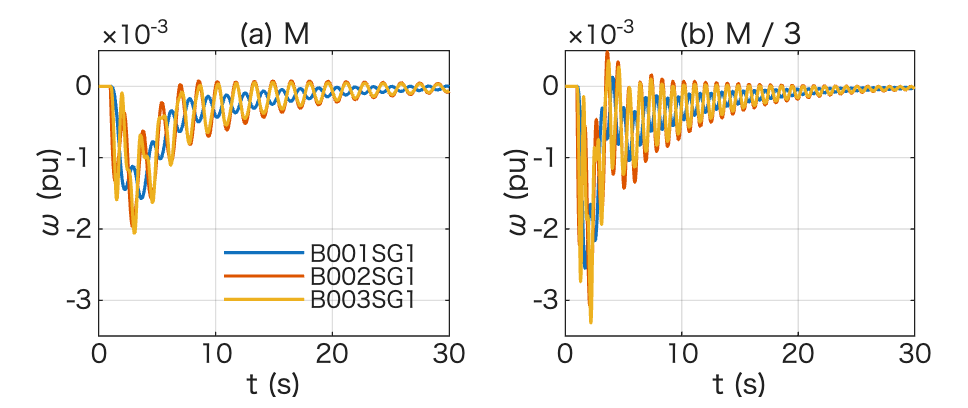

sr_title = ["(a) M", "(b) M / 3"];
figure(Position=[100, 100, 900, 380]);
tl = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
a_ax = gobjects(1, 2);
for i_case = 1:2
    a_ax(i_case) = nexttile(tl);
    rc_res{i_case}.plot_trajectory(Quantity="omega", Bus=["B001", "B002", "B003"], Parent=a_ax(i_case));
    title(a_ax(i_case), sr_title(i_case), FontWeight="normal");
    xlabel(a_ax(i_case), "t (s)");
    ylabel(a_ax(i_case), "ω (pu)");
end
linkaxes(a_ax, "xy");
set(a_ax, XLim=[0, 30], XGrid="on", YGrid="on", Box="on");
legend(a_ax(2), "off");
set(a_ax(1).Legend, Location="southeast", Box="off");

慣性が小さい右の図では、最初の低下が速く、深くなっています。ガバナが数秒のうちに低下を止め、AGC が数十秒かけて周波数を元に戻すのは、どちらの場合も同じです。

### 数値で確かめる

2 節の慣性中心の式と比べるため、慣性中心の周波数 $\omega_\mathrm{COI} = \sum_i M_i\omega_i / M_\mathrm{T}$ を求めます。`get_trajectory` に `Reference="COI"` を付けると、最後の列 `COI` にこの値が入ります。外乱の直後はまだガバナがほとんど動かず、電気出力もほとんど変わりません。そのため、機械入力の変化を $\Delta P$（ここでは −0.1 pu）とすると、2 節の式から、その傾きは $\mathrm{d}\omega_\mathrm{COI}/\mathrm{d}t \approx \Delta P / M_\mathrm{T}$ になるはずです。シミュレーションの 1.0〜1.1 秒の傾き、最も下がった値（最下点）とその時刻を求めて比べます。

for i_case = 1:2
    tab_coi = rc_res{i_case}.get_trajectory("omega", Reference="COI");
    lv_fit = tab_coi.t > 1 & tab_coi.t <= 1.1;
    rr_fit = polyfit(tab_coi.t(lv_fit), tab_coi.COI(lv_fit), 1);
    [r_nadir, i_nadir] = min(tab_coi.COI);
    fprintf("%s: 式の傾き %.2e pu/s、計算の傾き %.2e pu/s、最下点 %.4f pu（t = %.2f s）\n", ...
        sr_title(i_case), r_dP / rv_sumM(i_case), rr_fit(1), r_nadir, tab_coi.t(i_nadir));
end

(a) M: 式の傾き -7.69e-04 pu/s、計算の傾き -7.87e-04 pu/s、最下点 -0.0014 pu（t = 3.49 s）
(b) M / 3: 式の傾き -2.31e-03 pu/s、計算の傾き -2.46e-03 pu/s、最下点 -0.0022 pu（t = 1.80 s）


外乱の直後の傾きは、式から見積もった値 $\Delta P / M_\mathrm{T}$ とよく合い、慣性を 3 分の 1 にすると傾きもほぼ 3 倍になります。最下点は −0.0014 pu から −0.0022 pu へ深くなり（60 Hz の系統でそれぞれ −0.08 Hz と −0.13 Hz）、その時刻も外乱から約 2.5 秒後から約 0.8 秒後へ早まります。ガバナが出力を増やすまでの時間は同じなので、その間に周波数がより大きく下がるためです。この系統は小さいため値も小さいですが、大きな電源の脱落では、周波数が下がりすぎる前にガバナが間に合うかどうかが問題になります。

このような系統を安定に保つために、慣性のようにふるまうインバータの制御や蓄電池、新しい制御方式が研究され、導入されています。この講義で扱う時間シミュレーション（Part 3）、近似線形化（Part 5）、制御器の設計（Part 8）は、こうした考えを確かめるための道具です。

**注意**: 1 台だけ変えるときは、`net9.get_element("B002SG1")` で機器を取り出し、その `tab_parameter.dynamics.M` に書き込んでもかまいません。ガバナとAGC の付け方は Part 1 と Part 8 で、入力の変化 `add_input` の書き方は Part 3 で扱います。

## まとめ

- 電力系統は発電・送電・配電・需要の 4 つの段階からなり、送電網は母線とブランチの網の目です。損失が電圧の 2 乗に反比例するので、高い電圧で送ります。

- 需要と供給は常に一致させる必要があります。ずれは同期発電機の回転子の運動エネルギーでまかなわれます。発電機はそれぞれ自分の動揺方程式に従い、送電網を通して結び付いています。同期した状態では、どの母線の周波数も同じ値（系統周波数）になります。需給がつり合わないと、ガバナと AGC がなければ、系統周波数は定格からずれた値で落ち着きます。電圧は母線ごとに異なり、無効電力に左右されます。

- 現象の時間スケールはマイクロ秒から 1 日まで広がり、GUILDA の時間シミュレーションは発電機の動揺と制御の範囲を扱います。

- 潮流計算はある瞬間の運転状態を連立方程式で求め、時間シミュレーションはそこから外乱の後の動きを微分方程式で求めます。

- 慣性が小さくなると、需給のずれに対する周波数の低下が速く、深くなります。外乱の直後の慣性中心の周波数の傾きは $\Delta P/M_\mathrm{T}$ で見積もれます。

**次の Part**: Part 1「電力系統の作成と機器の種類」では、母線・ブランチ・機器・制御器を組み合わせて系統モデルを作る方法と、機器のモデルを扱います。

[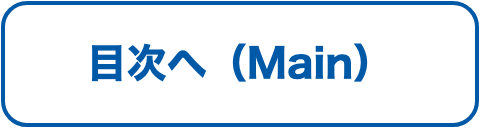](matlab:open('Main.mlx'))　　[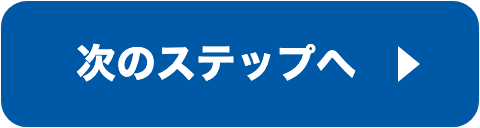](matlab:open('Part1_NetworkComponents.mlx'))